# Plot results of FWI tests

## Introduction

In this file we will make smothed versions of velocity model optimal for FSM and FWI

**Author**: Ivan Abakumov

**Publication date**: 19.06 2019

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB folder

clear all; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
addmypath;
current_folder = pwd;

INV_settings;

## Plot result of tomography

callTOMOcomputeObjective=111;

F = zeros(1, callTOMOcomputeObjective+1); 
Gr = zeros(G.nx, G.nz, callTOMOcomputeObjective+1); 
dV = zeros(G.nx, G.nz, callTOMOcomputeObjective+1); 

fromfolder = '/home/ivan/Desktop/FWI_DIFF/result/TOMO/';

for i=0:callTOMOcomputeObjective
    fname_G = [fromfolder tomobasename '_G_' num2str(i) '.mat'];
    fname_F = [fromfolder tomobasename '_F_' num2str(i) '.mat'];
    fname_dV = [fromfolder tomobasename '_dv_' num2str(i) '.mat'];
    F(i+1) = MLD(fname_F); 
    Gr(target.xx,target.zz,i+1) = MLD(fname_G); 
    dV(target.xx,target.zz,i+1) = MLD(fname_dV); 
end

figure(1)
fig = figure('Position', [900 400 570 360])

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 570 360]
       Units: 'pixels'

  Show all properties


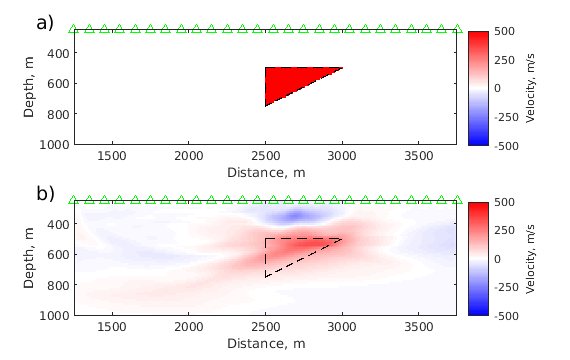

subplot(2,1,1)
imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'a)','FontSize',14);

subplot(2,1,2)
i=111;
imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)'),2))
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'b)','FontSize',14);

## Plot result of FWI (no diffractions)

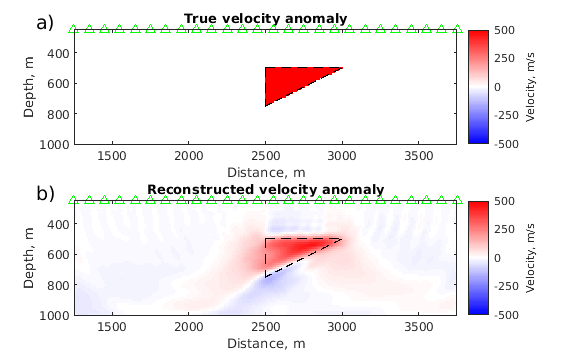

callFWIcomputeObjective=55;
F = zeros(1, callFWIcomputeObjective+1); 
Gr = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 
dV = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 

fromfolder = '/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_only/';

for i=0:callFWIcomputeObjective
    fname_G = [fromfolder fwibasename '_G_' num2str(i) '.mat'];
    fname_F = [fromfolder fwibasename '_F_' num2str(i) '.mat'];
    fname_dV = [fromfolder fwibasename '_dv_' num2str(i) '.mat'];
    F(i+1) = MLD(fname_F); 
    Gr(target.xx,target.zz,i+1) = reshape(MLD(fname_G), length(target.xx), length(target.zz)); 
    dV(target.xx,target.zz,i+1) = reshape(MLD(fname_dV), length(target.xx), length(target.zz)); 
end


figure(2)
subplot(2,1,1)
imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
i=56;
imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)'),2))
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

## Plot result of FWI

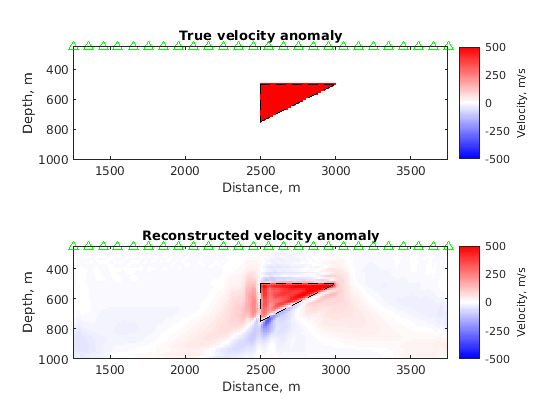

callFWIcomputeObjective=59;
F = zeros(1, callFWIcomputeObjective+1); 
Gr = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 
dV = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 

fromfolder = '/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_ref_diff/';

for i=0:callFWIcomputeObjective
    fname_G = [fromfolder fwibasename '_G_' num2str(i) '.mat'];
    fname_F = [fromfolder fwibasename '_F_' num2str(i) '.mat'];
    fname_dV = [fromfolder fwibasename '_dv_' num2str(i) '.mat'];
    F(i+1) = MLD(fname_F); 
    Gr(target.xx,target.zz,i+1) = reshape(MLD(fname_G), length(target.xx), length(target.zz)); 
    dV(target.xx,target.zz,i+1) = reshape(MLD(fname_dV), length(target.xx), length(target.zz)); 
end


figure(3)
subplot(2,1,1)
imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
i=59;
%imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)),2)')
imagesc(G.xx, G.zz, squeeze(dV(:,:,i))')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

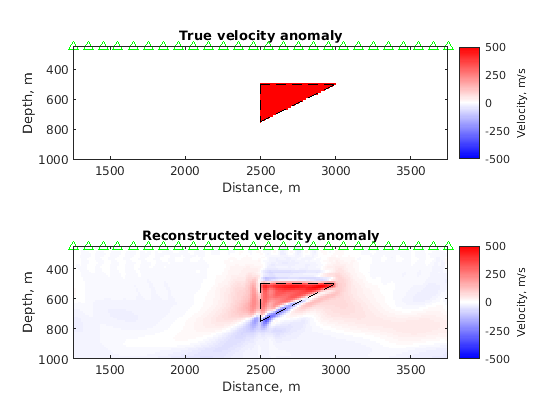


figure(4)
subplot(2,1,1)
imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
i=29;
%imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)),2)')
imagesc(G.xx, G.zz, squeeze(dV(:,:,i))')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

## Figure for paper (FWI)

callFWIcomputeObjective=55;
F = zeros(1, callFWIcomputeObjective+1); 
Gr = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 
dV = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 

fromfolder = '/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_only/';

for i=0:callFWIcomputeObjective
    fname_G = [fromfolder fwibasename '_G_' num2str(i) '.mat'];
    fname_F = [fromfolder fwibasename '_F_' num2str(i) '.mat'];
    fname_dV = [fromfolder fwibasename '_dv_' num2str(i) '.mat'];
    F(i+1) = MLD(fname_F); 
    Gr(target.xx,target.zz,i+1) = reshape(MLD(fname_G), length(target.xx), length(target.zz)); 
    dV(target.xx,target.zz,i+1) = reshape(MLD(fname_dV), length(target.xx), length(target.zz)); 
end


figure(5)
fig = figure('Position', [900 400 570 720])

fig =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 570 720]
       Units: 'pixels'

  Show all properties


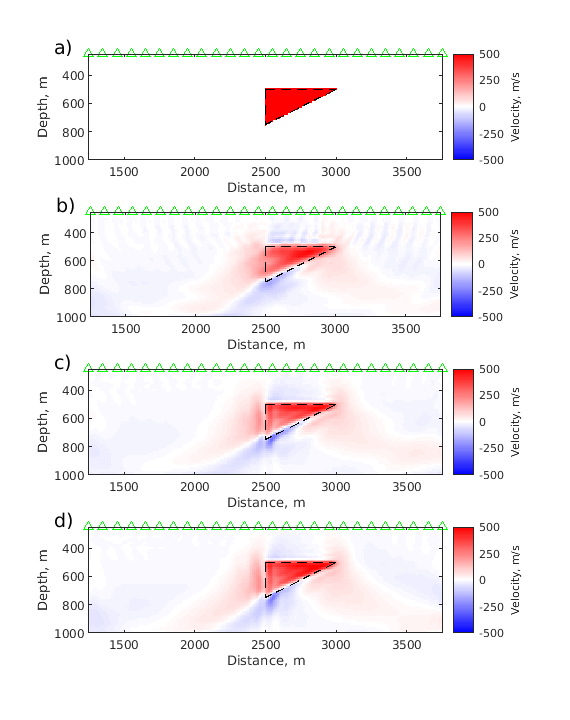

subplot(4,1,1)
imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'a)','FontSize',14);


subplot(4,1,2)
i=56;
%imagesc(G.xx, G.zz, squeeze(dV(:,:,i)'))
imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)'),1))
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'b)','FontSize',14);

callFWIcomputeObjective=59;
F = zeros(1, callFWIcomputeObjective+1); 
Gr = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 
dV = zeros(G.nx, G.nz, callFWIcomputeObjective+1); 

fromfolder = '/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_ref_diff/';

for i=0:callFWIcomputeObjective
    fname_G = [fromfolder fwibasename '_G_' num2str(i) '.mat'];
    fname_F = [fromfolder fwibasename '_F_' num2str(i) '.mat'];
    fname_dV = [fromfolder fwibasename '_dv_' num2str(i) '.mat'];
    F(i+1) = MLD(fname_F); 
    Gr(target.xx,target.zz,i+1) = reshape(MLD(fname_G), length(target.xx), length(target.zz)); 
    dV(target.xx,target.zz,i+1) = reshape(MLD(fname_dV), length(target.xx), length(target.zz)); 
end

subplot(4,1,3)
i=39;
imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)),1)')
%imagesc(G.xx, G.zz, squeeze(dV(:,:,i))')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'c)','FontSize',14);

subplot(4,1,4)
i=59;
imagesc(G.xx, G.zz, SME(squeeze(dV(:,:,i)),1)')
%imagesc(G.xx, G.zz, squeeze(dV(:,:,i))')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'d)','FontSize',14);